# **TGAS Model TestBench Instructions**

Run the setupscript,which initializes data used by the model, such as the scenario,vehicle and controller parameters.

setupscript;

Open the simulink model.

mdl = 'TGASMODEL';
open_system(mdl);

Open the Commandd APP. In Commandd APP you` can set the initial value of ego vehicle position,velocity,and set the command to let the vehicle switch lane. 

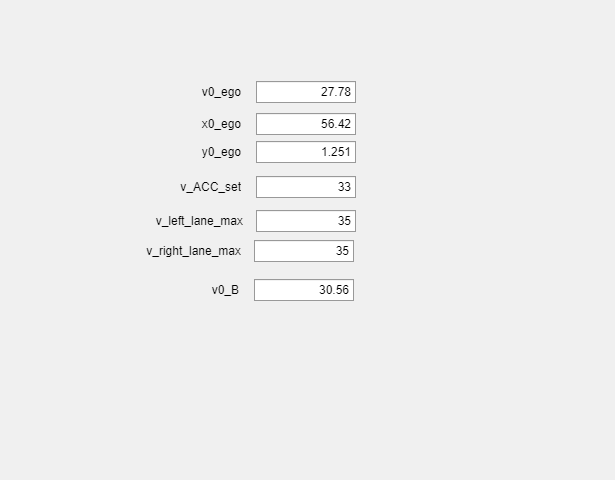

Commandd;

Open the Bird's-Eye Scope,and find signals,then run.

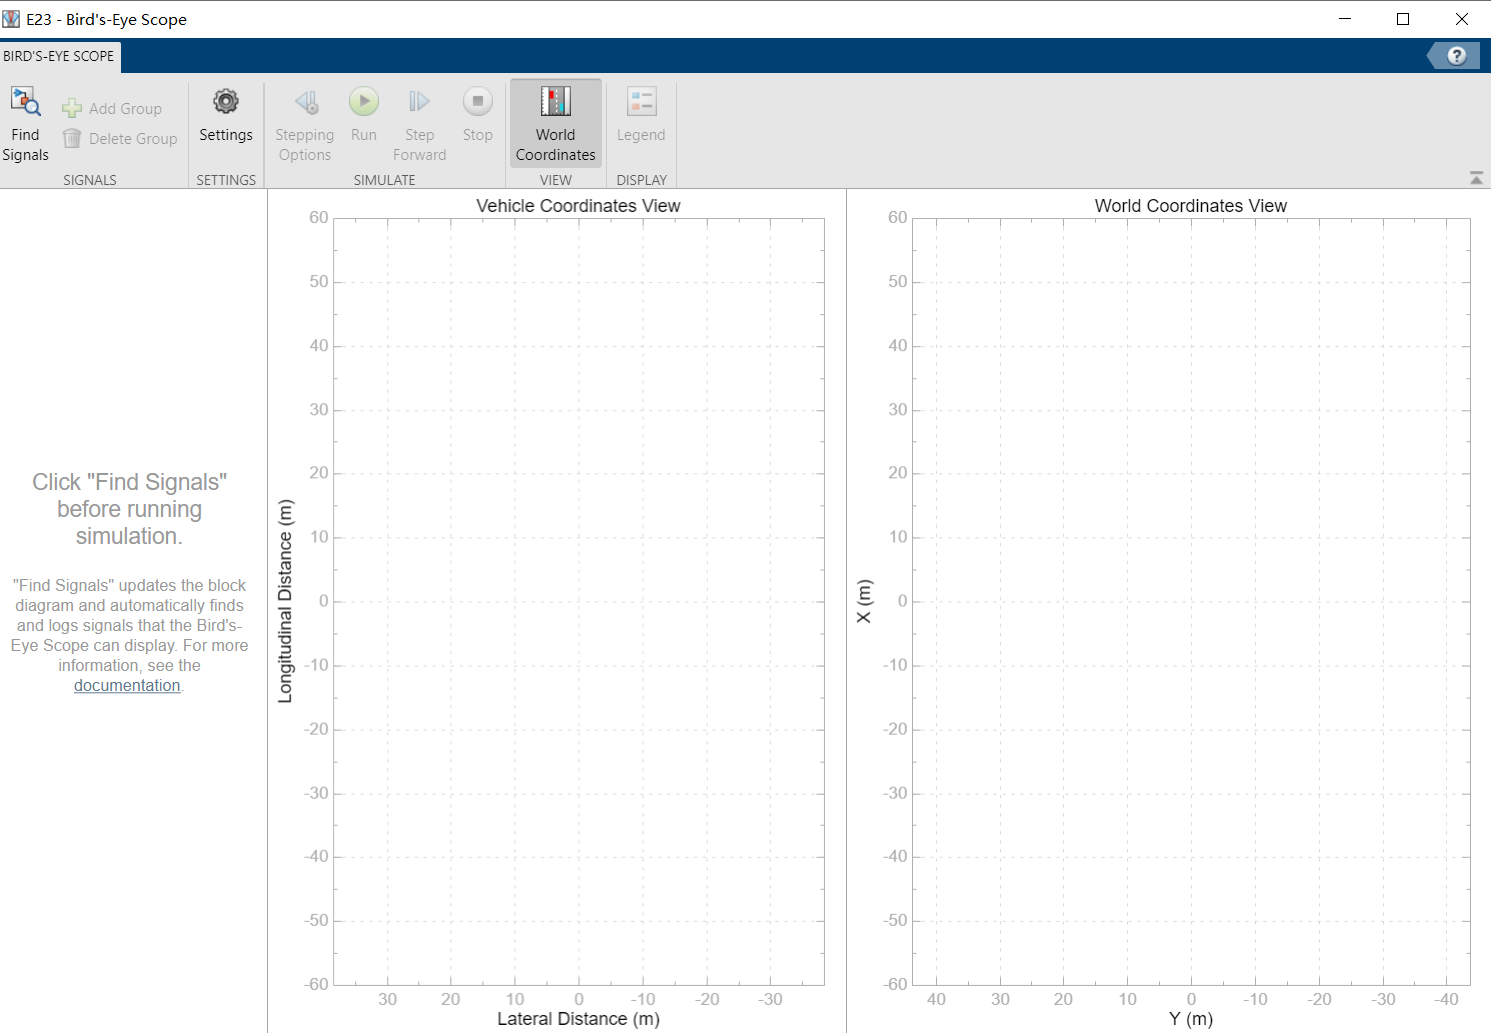

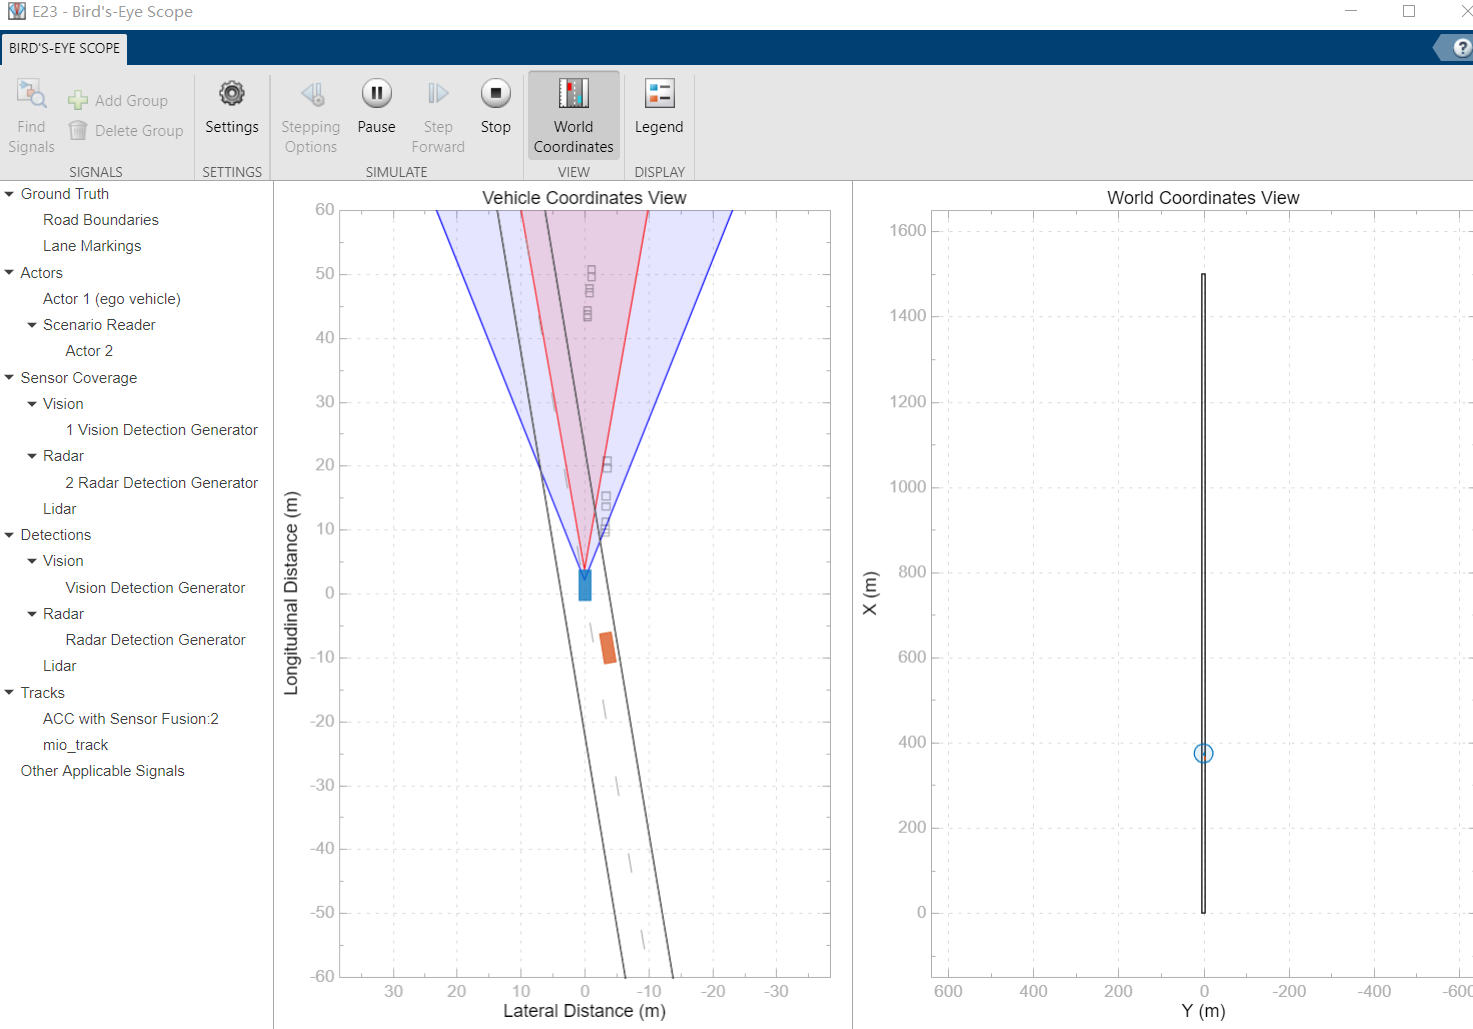

# **Introduction**

This model achieves the ACC, Lane change and LKAS maneuvers.

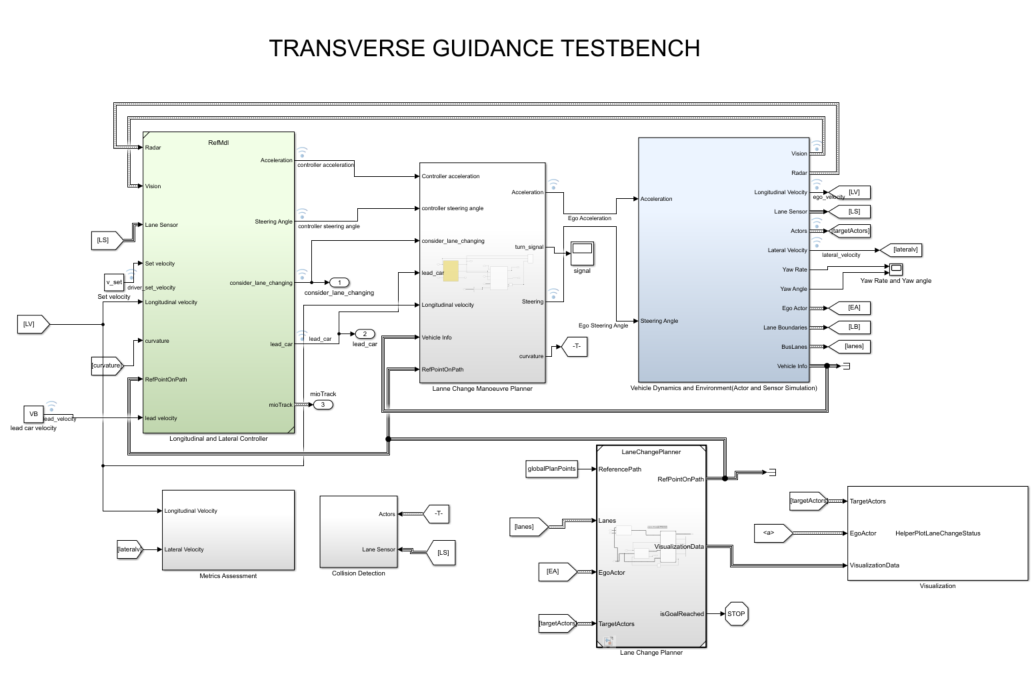

There are 3 main sub-blocks: 1) Longitudinal and Lateral Controller 2) Lane Change Manoeuvre Planner and 3) Vehicle Dynamics block

The longitudinal and lateral controller has two parts,one is Tracking and Sensor Fusion,another one is Estimate Lane Center.

The Tracking and Sensor Fusion subsystem processes vision and radar detections coming from the Vehicle and Environment subsystem and generates a comprehensive situation picture of the environment around the ego vehicle. Also, it provides the ACC with an estimate of the closest car in the lane in front of the ego vehicle.It also output lear_car and consider_lane_changing which are used in autonomous mode.

The detail of this subsystem can be found in the website:

[https://www.mathworks.com/help/driving/examples/adaptive-cruise-control-with-sensor-fusion.html](https://www.mathworks.com/help/driving/examples/adaptive-cruise-control-with-sensor-fusion.html)

Lateral and Longitudiinal controller sub-block contains Path Following Controller.

It calculates the acceleration/deceleration based and longitudinal velocity of Ego-Car and relative  distance, relative velocity of Ego-Car with respect to Lead-Car on same lane.

It also calculates a steering angle for the Ego-Car based on the following inputs: 1. Longitudinal velocity of Ego-Car 2. Lateral deviation (derived from Lane Detections) 3. Relative yaw angle (derived from Lane Detections).

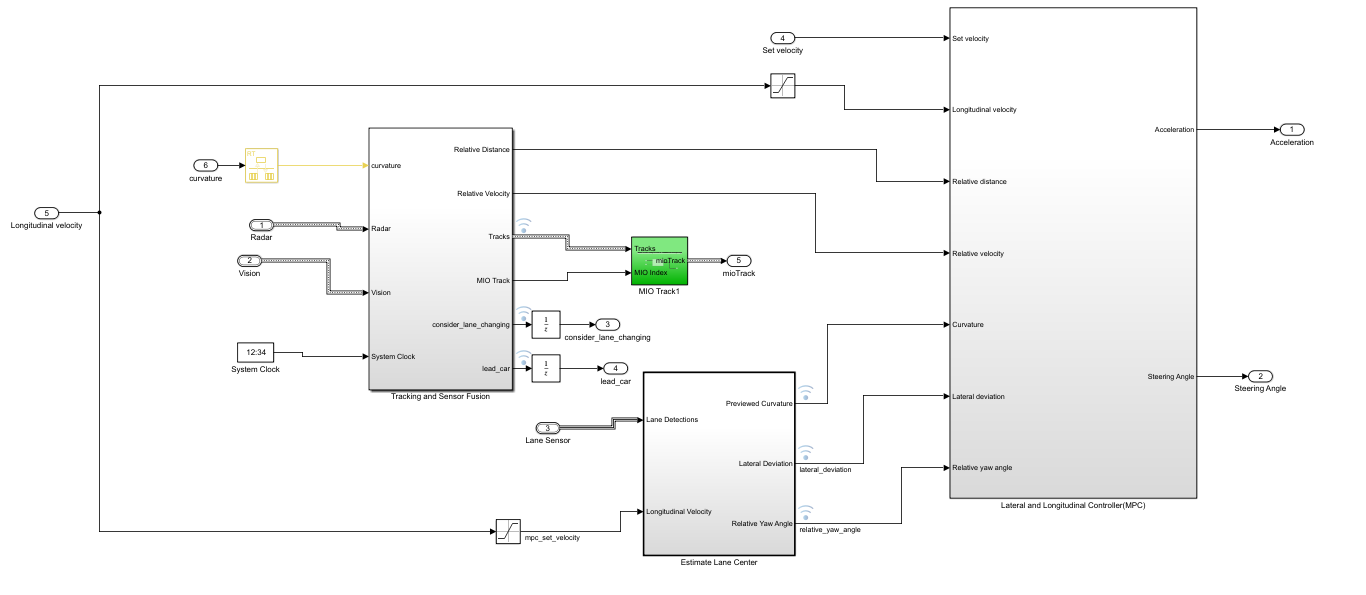

 Lane Change and Manoeuvre Planner has substems:

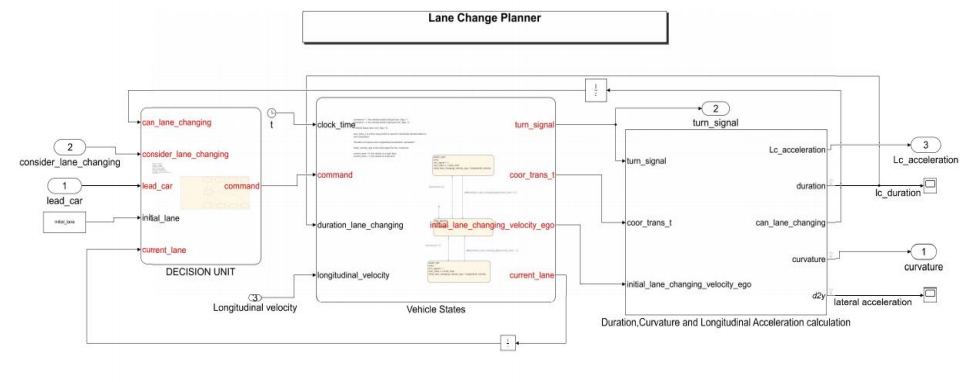

(1)Vehicle States defines different vehicle states,each state correspond to a  maneuver,it will output the needed information to the algorithm.

(2)Duration,Curvature and Longitudinal Acceleration calculation,calculates the acceleration,curvature and duration for different maneuver,outputs the can_lane_changing signal to indicate whether it is allowed to change lane.

(3)Longitudinal Acceleration decide decides which acceleration to use for different maneuver.

(4)Steering Angle decide decides which steering angle to use for different maneuver.

# **Vehicle States**

The Vehicle State flowchart defines 2 main states:

1.switch left and right straight

2. Lane keeping

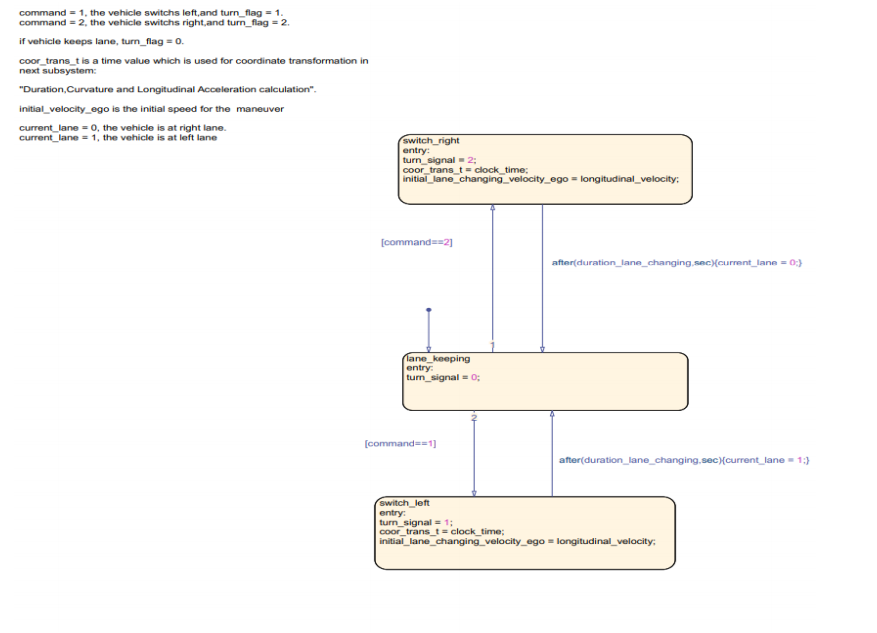

# **Duration,Curvature and Longitudinal Acceleration calculation(L3.2)**

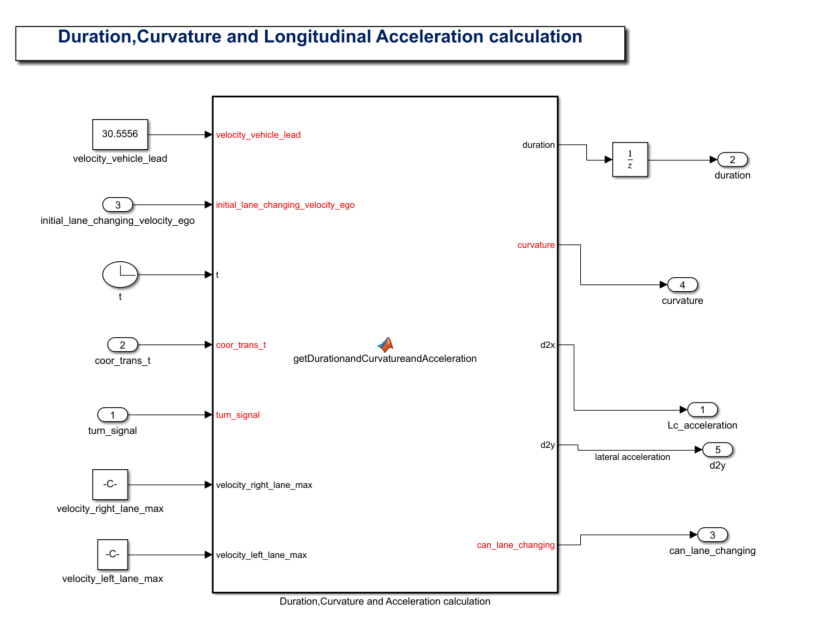

This matlab function calculates the duration,longitudinal acceleration and curvature for different maneuver,it also outputs the can_lane_changing flag,but now it is set to one.

# **Longitudinal Acceleration decide(L3.4)**

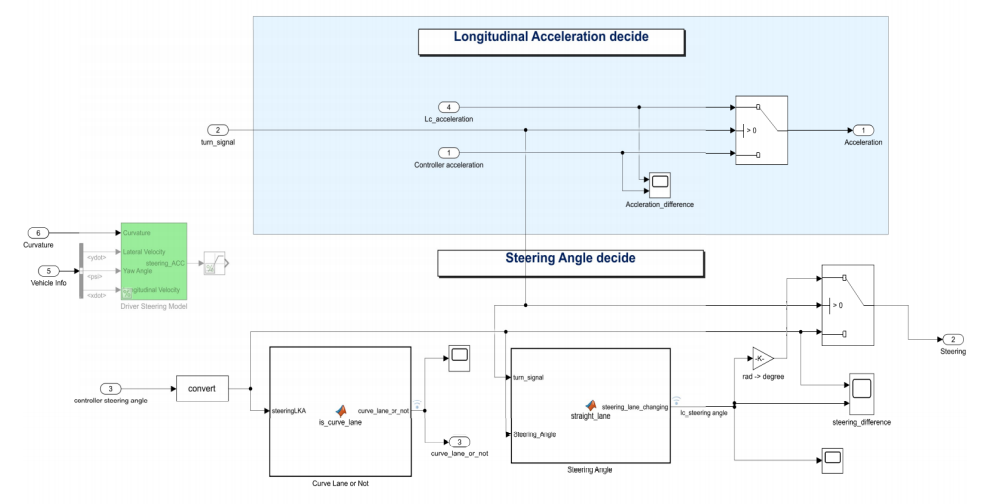

When turn_signal = 0,which means the vehicle is keeping its lane,the acceleration is for ACC and steering angle is for LKAS,otherwise it is from Lane change planner unit.